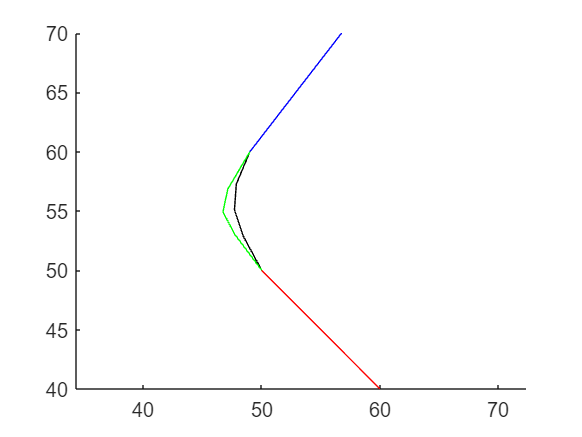

figure
hold on
lane1 = [100,0;50,50];
lane2 = [49,60;80,100];
plot(lane1(:,1),lane1(:,2),'r')
plot(lane2(:,1),lane2(:,2),'b')
axis([25,60,40,70])
axis equal
k1 = 0.6;
k2 = 1-k1;
x1 = lane1(end-1,1);
x3 = lane1(end,1);
x2 = k1*x3+k2*x1;
x4 = lane2(1,1);
x6 = lane2(2,1);
x5 = k1*x4+k2*x6;
y1 = lane1(end-1,2);
y3 = lane1(end,2);
y2 = k1*y3+k2*y1;
y4 = lane2(1,2);
y6 = lane2(2,2);
y5 = k1*y4+k2*y6;

intX = makima(1:6,[x1;x2;x3;x4;x5;x6],3:0.25:4);
intY = makima(1:6,[y1;y2;y3;y4;y5;y6],3:0.25:4);
shape = genIntLaneShape(lane1,lane2);
plot(intX,intY,'k')
plot(shape(:,1),shape(:,2),'g')
hold off

tic
for i = 1:1000
shape = genIntLaneShape(lane1,lane2);
end
toc/1000

ans = 7.2651e-05

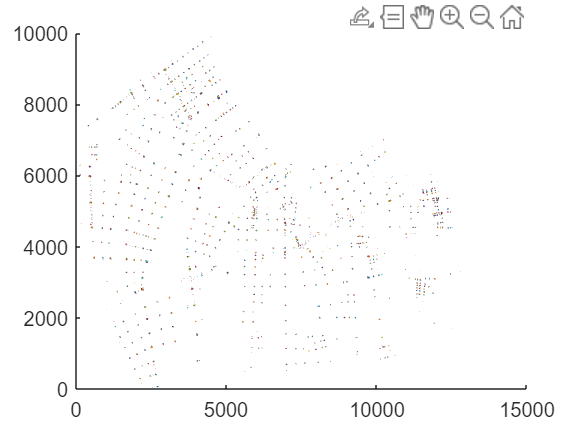

figure 
hold on
keys = entity_dict.keys;
for i = 1:length(keys)
    key = keys{i};
    entity = entity_dict{key};
    if isa(entity,'Edge_SUMO')
        if ~strncmp(key,':',1)
            if isKey(connection_dict,key)
                for j = 1:connection_dict{key}.connection_num
                    connection = connection_dict{key}.connections{j};
                    fromLaneID = [connection.from '_' num2str(connection.fromLane)];
                    viaLaneID = connection.via;

                    toLaneID = [connection.to '_' num2str(connection.toLane)];
                    viaLaneEntity = entity_dict{viaLaneID};
                    viaLaneEntity.shape = genIntLaneShape(entity_dict{fromLaneID}.shape,entity_dict{toLaneID}.shape);
                    entity_dict{viaLaneID} = viaLaneEntity;
                    if strcmp(viaLaneID,':cluster_2426624752_2426624753_21_0')
                        disp('找到啦')
                    end
                    % plot(viaLaneEntity.shape(:,1),viaLaneEntity.shape(:,2))
                end
            end
        end
    end

end
hold off

% 分开写的代码
f1 = @() separate_code();
time1 = timeit(f1);

% 合并后的代码
f2 = @() combined_code();
time2 = timeit(f2);

fprintf('分开写的代码执行时间: %f 秒\n', time1);

分开写的代码执行时间: 0.006876 秒


fprintf('合并后的代码执行时间: %f 秒\n', time2);

合并后的代码执行时间: 0.005792 秒



% 分开写的代码函数

function separate_code()
    k1 = 2*ones(1000);
    k2 = 3*ones(1000);
    x1 = k1 + k2;
    p = x1.^2;
end

% 合并后的代码函数
function combined_code()
    k1 = 2*ones(1000);
    k2 = 3*ones(1000);
    p = (k1 + k2).^2;
end